# Hypothesis Testing

Hypothesis testing is a common method of drawing inferences about a population based on statistical evidence from a sample.

Comparing a Single Mean to a Specified Value

See hand notes dated 10/26/21 13:05

From Montgomery (2019):

Problem Statement:

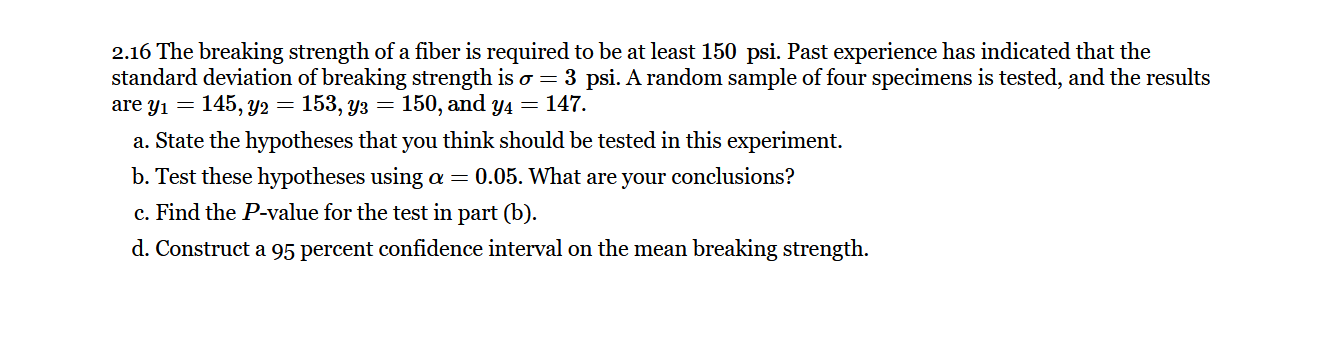

imshow('2.16_Montgomery.png')

y = [145;153;150;147];
yMean = mean(y)

yMean = 148.7500

mu = 150;
sigma = 3;
n = numel(y);

a. The hypothesis that should be tested, should compare the population mean $\mu$ to a specified value, $\mu_0$.


$$H_0: \mu = \mu_0$$



$$H_1: \mu > \mu_0$$


The alternative hypothesis is one sided.

A **one-sample Z-test statistic** should be used to test the hypothesis;


$$Z_0 = \frac{\bar y - \mu_0} {\sigma/\sqrt{n}}$$
 

[h,p,ci,zval] = ztest(y,mu,sigma,"Alpha",.05,"Tail","right")

h = 0

p = 0.7977

ci =   146.2827
       Inf


zval = -0.8333

An h equal to zero means that the test failed to reject the null hypothesis; indicating that the data in the vector `y` comes from a normal distribution with a mean $\mu = 150$.

b. From the Z-test statistic and in corroboration with the P-value approach, we **fail to reject **$H_0$ and therefore infer that the mean sample of specimens tested do not have a breaking strength of at least 150 psi.

c. The P-value of 0.80 is much greater than the level of significance, corroborating the above inference.

d. Since we already know that the means $\mu_0$ and $\mu$ differ, thus a hypothesis test on $\mu_1 = \mu_0$ is of little interest in the practical world; the confidence 'interval' (for a one sided test, there will only be one limit) at what point the mean sample is located with a 95 % confidence measure. I.e., the above 146.28 psi indicates that the mean sample is located at that point - with 95% confidence (note that this is different than the 'actual' mean calculated, this is because we are now factoring in the confidence). 

%% Continue here... 10/26/21.... %%%%

%%% Complete this prior to March 2022 term %%%

As a side bar, prior to performing a hypothesis test, it is worthwhile to calculate the choice of sample size. See Montgomery, 2.4.3, p. 39.

If we are interested in detecting the difference between the lowest measured data point (145) and the breaking strength required, then, because we know the means are not equal, so that $\delta = \mu_1-\mu_2$

The probability of a Type II error $\beta$ depends on the true difference in means $\delta$

Recall that the type II error, is a 'miss' an error of inclusion; e.g., declaring a person innocent even though guilty.

$\beta$ vs $\delta$ is the **operating characteristic curve**, an alternative to this is the **power curve, **which plots $1-\beta$ vs the $n$ sample size for a specified $\delta$

Some power curves are expressed as a ratio to the common standard deviation


$$\delta = \frac{|\mu_1 - \mu_2|}{\sigma}$$


Two observations (pun intended):

- The greater the difference in means, the higher the power (smaller type II error probability).

- As the sample size gets larger, the power of the tests gets larger (type II error probability gets smaller) for a given difference in means and significance level $\alpha$.

% Number of replicates calculation:
nout = sampsizepwr('z',[150 3], 145, .95) % Using a z-test because the standard deviation is known 

nout =      5


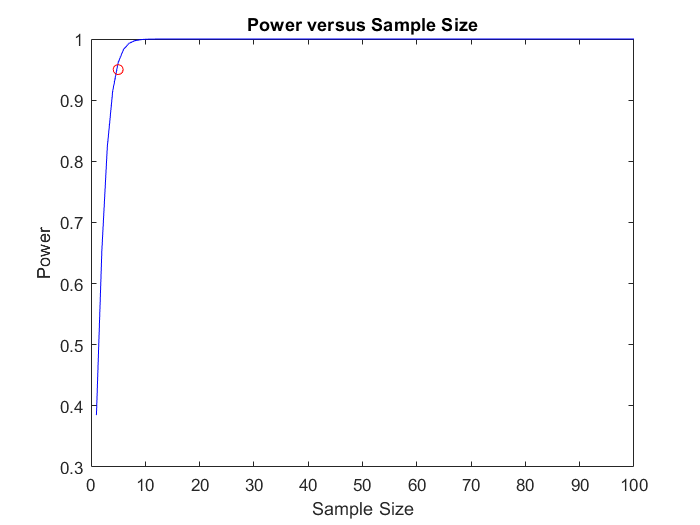

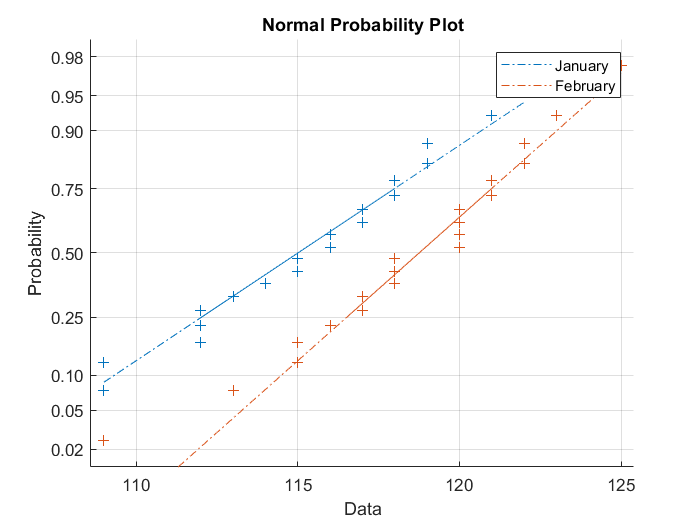

h =      0


h =      0


sample_means =        115.15        118.5


h =      0


pvalue =       0.86682


ci =         1.134
        1.169


h =      1


pvalue =    0.00049517


ci =        1.1675
       1.2025


h =      1


sig =     0.0082863


ci =       -5.7845
     -0.91552


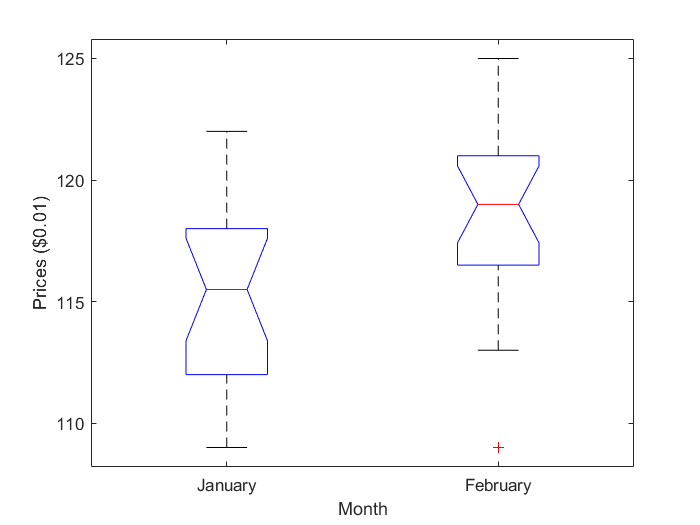

p =     0.0095202


h = logical
   1


% Generate a power curve to visualize sample size versus the power of the
% test

nn = 1:100;
pwrout = sampsizepwr('z',[150 3],145,[],nn);
figure;
plot(nn,pwrout,'b-',nout,0.95,'ro')
title('Power versus Sample Size')
xlabel('Sample Size')
ylabel('Power')

References:

Montgomery, D. C. (2019). *Design and Analysis of Experiments, Enhanced eText* (10th Edition). Wiley Global Education US. [https://bookshelf.vitalsource.com/books/9781119492443](https://bookshelf.vitalsource.com/books/9781119492443)